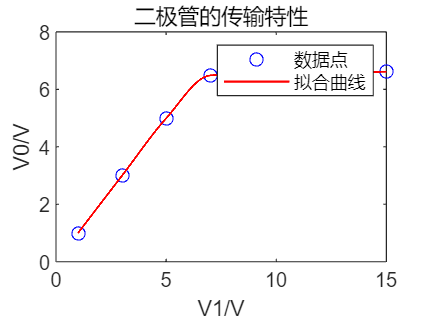

x = [1 3 5 7 9 11 15];
y = [0.999 2.998 4.990 6.483 6.551 6.580 6.613];
xx = 1:0.001:15;
yy = interp1(x,y,xx,"pchip");
figure;
plot(x,y,'o b')
hold on;
plot(xx,yy,'-r','LineWidth',1);
title("二极管的传输特性");
xlabel("V1/V"), ylabel("V0/V"),legend('数据点','拟合曲线');

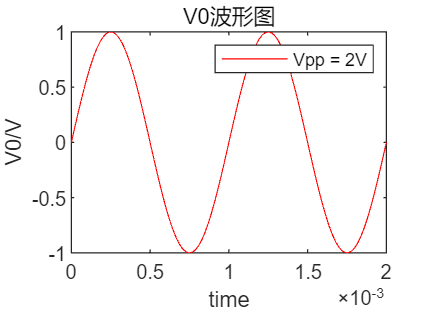

x = [2,4,8,10,12,14,15];
y1 = [1.00 1.01 4.00 5.10 6.08 6.60 6.64];
y2=  [1.01 1.02 2.41 2.50 2.50 2.44 2.44];
z1 = 2.44;
z2 = 6.60;
p = 7.5;
y11 = z.*ones(50);
y22 = -z2.*ones(50);
n = linspace(0,0.002,100);
n1 = linspace(0,asin(z1/p)/2000/pi,50);
n11 = linspace(asin(z1/p)/2000/pi,0.0005-asin(z1/p)/2000/pi,50);
n111 = linspace(0.0005-asin(z1/p)/2000/pi,0.0005,50);

n02 = linspace(0.0005,asin(z2/p)/2000/pi+0.0005,50);
n22 = linspace(asin(z2/p)/2000/pi+0.0005,0.001-asin(z2/p)/2000/pi,50);
n222 = linspace(0.001-asin(z2/p)/2000/pi,0.001,50);

n2 = linspace(0.0005,0.001,50);
figure;
plot(n,sin(n*2000*pi),'r');
title("V0波形图");
xlabel("time"), ylabel('V0/V');
legend('Vpp = 2V');

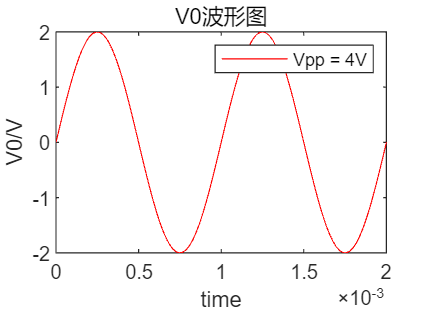

figure;
plot(n,2.*sin(n*2000*pi),'r');
title("V0波形图");
xlabel("time"), ylabel('V0/V');
legend('Vpp = 4V');

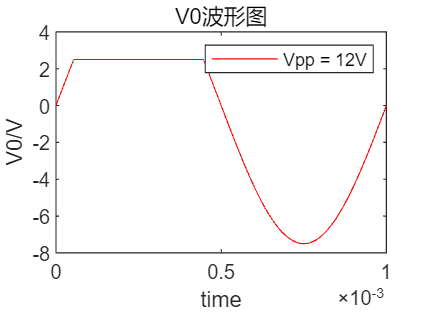

figure;
plot(n1,p*sin(n1*2000*pi),'r')
hold on;
plot(n11,y11,'r');
hold on ;
plot(n111,p*sin(n111*2000*pi),'r');
hold on ;
plot(n2,p*sin(n2*2000*pi),'r');
title("V0波形图");
xlabel("time"), ylabel('V0/V');
legend('Vpp = 12V');

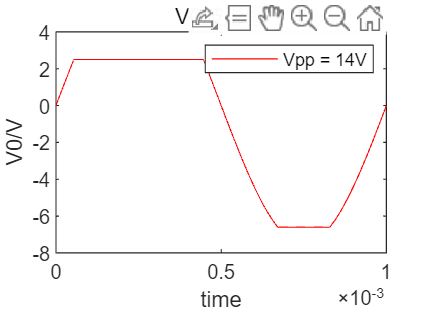


figure;
plot(n1,p*sin(n1*2000*pi),'r')
hold on;
plot(n11,y11,'r');
hold on ;
plot(n111,p*sin(n111*2000*pi),'r');
hold on ;
plot(n02,p*sin(n02*2000*pi),'r');
hold on;
plot(n22,y22,'r');
hold on;
plot(n222,p*sin(n222*2000*pi),'r');
title("V0波形图");
xlabel("time"), ylabel('V0/V');
legend('Vpp = 14V');

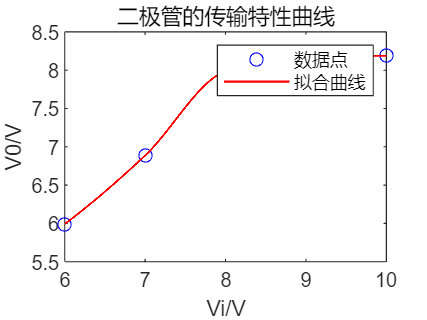

x = [6 7 8 9 10];
y = [5.992 6.887 7.985 8.188 8.190];
xx = 6:0.001:10;
yy = interp1(x,y,xx,"pchip");
figure;
plot(x,y,'o b')
hold on;
plot(xx,yy,'-r','LineWidth',1);
title("二极管的传输特性曲线");
xlabel("Vi/V"), ylabel("V0/V"),legend('数据点','拟合曲线');